# Robust Unconstrained RHC

We'll use the following toolboxes: Yalmip and Sedumi as a solver.

First of all, let's clear the environment:

clear; close all; clc;
yalmip('clear'); % used to clean yalmip's internal db

Define the **data:**

parameters.rho = 10;
parameters.Ts=0.1;
parameters.Kmin = 2;
parameters.Kmax = 4;
parameters.M=1;
parameters.b=1;

Ts=parameters.Ts;
Kmin=parameters.Kmin;
Kmax = parameters.Kmax;
M = parameters.M;
b=parameters.b;

% We add uncertainty
A1=[1 Ts; -Kmin*Ts/M 1-b*Ts/M];
A2=[1 Ts; -Kmax*Ts/M 1-b*Ts/M];

B=[0; Ts/M];


[parameters.n,parameters.m]=size(B);

Cz = [eye(parameters.n); zeros(parameters.m, parameters.n)];
Dz = parameters.rho .* [zeros(parameters.n, parameters.m); eye(parameters.m)];

x_0 = [8; -25];

Define the **decision** **variables**:

n=parameters.n; m=parameters.m;

Q = sdpvar(n,n)

Linear matrix variable 2x2 (symmetric, real, 3 variables)
Coefficient range: 1 to 1


Y = sdpvar(m,n)

Linear matrix variable 1x2 (full, real, 2 variables)
Coefficient range: 1 to 1


gamma = sdpvar(1)

Linear scalar (real, 1 variable)
Coefficients range: 1 to 1


Build **constraints **and define **shaping matrices Q1 **and **R**:

Q1 = eye(n,n)

Q1 =      1     0
     0     1


R = eye(m)

R = 1


S = [1 x_0'; x_0 Q];

T1 = [   Q            Q*A1'+Y'*B'             Q*(Q1)^0.5            Y'*(R)^0.5;
        A1*Q+B*Y           Q                   zeros(n,n)           zeros(n,m)                       
        (Q1)^0.5*Q   zeros(n,n)                 gamma*eye(n)       zeros(n,m)     
        (R)^0.5*Y    zeros(m,n)               zeros(m,n)           gamma*eye(m)  ];

T2 = [   Q            Q*A2'+Y'*B'          Q*(Q1)^0.5            Y'*(R)^0.5;
        A2*Q+B*Y     Q                   zeros(n,n)        zeros(n,m)                       
        (Q1)^0.5*Q   zeros(n,n)          gamma*eye(n)       zeros(n,m)     
        (R)^0.5*Y    zeros(m,n)          zeros(m,n)           gamma*eye(m)  ];

Defining **constraints**:

C = [S>=0, T1>=0, T2>=0, Q>=0]

+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|              Constraint|   Coefficient range|
+++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality 3x3|             1 to 25|
|   #2|   Matrix inequality 7x7|            0.1 to 1|
|   #3|   Matrix inequality 7x7|            0.1 to 1|
|   #4|   Matrix inequality 2x2|              1 to 1|
+++++++++++++++++++++++++++++++++++++++++++++++++++++


Define **solver **and prepare **optimization**:

opt = sdpsettings('solver','sedumi');

sol = optimize(C,gamma,opt);

SeDuMi 1.3.7 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 6, order n = 20, dim = 112, blocks = 5
nnz(A) = 56 + 0, nnz(ADA) = 36, nnz(L) = 21
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            6.83E+00 0.000
  1 :  -4.38E+01 1.81E+00 0.000 0.2656 0.9000 0.9000   0.93  1  1  4.4E+00
  2 :  -1.64E+02 4.51E-01 0.000 0.2490 0.9000 0.9000  -0.19  1  1  2.8E+00
  3 :  -4.26E+02 1.16E-01 0.000 0.2570 0.9000 0.9000  -0.29  1  1  1.7E+00
  4 :  -8.44E+02 3.86E-02 0.000 0.3332 0.9000 0.9000  -0.20  1  1  1.1E+00
  5 :  -1.59E+03 1.21E-02 0.000 0.3138 0.9000 0.9000  -0.13  1  1  6.5E-01
  6 :  -2.49E+03 4.77E-03 0.000 0.3932 0.9000 0.9000   0.01  1  1  4.0E-01
  7 :  -3.25E+03 2.33E-03 0.000 0.4891 0.9000 0.9000   0.16  1  1  2.7E-01
  8 :  -3.98E+03 1.18E-03 0.000 0.5054 0.9000 0.9000   0.24  1  1  1.8E-01
  9 :  -4.70E+03 5.75E-04 0.000 0.4875 0.9000 0.9000   0.32  1  1  1.2E-01
 10 :  -5.34E+03

**Most important slide -> analyze error flags:**

if sol.problem == 0
    % if it has a solution, display it
    solution = value(gamma)
else
    disp('Orrore')
    sol.info
    yalmiperror(sol.problem)
end

solution = 6.6368e+03

Let's compute **F **e **P**:

F = - value(Y)*inv(value(Q)) % change sign

F =     0.3649    0.9969


P = solution*inv(value(Q))

P =    41.2629    7.1800
    7.1800   10.9888


# Plot the ellissoid

Q = value(Q)

Q =   181.4747 -118.5740
 -118.5740  681.4393


lambda = rand()

lambda = 0.5469

A = lambda * A1 + (1-lambda) * A2

A =     1.0000    0.1000
   -0.2906    0.9000



x = zeros(n, 51);  
u = zeros(m, 50);  

x(:,1) = x_0;     

for i = 1:150
    u(:,i) = -F * x(:,i);          
    x(:,i+1) = A * x(:,i) + B * u(:,i);  
end

x = x(:,1:150)

x =     8.0000    5.5000    3.2375    1.2469   -0.4521   -1.8526   -2.9587   -3.7833   -4.3465   -4.6734   -4.7929   -4.7357   -4.5331   -4.2160   -3.8140   -3.3543   -2.8617   -2.3577   -1.8607   -1.3859   -0.9450   -0.5468   -0.1972    0.1005    0.3451    0.5377    0.6805    0.7772    0.8323    0.8510    0.8387    0.8011    0.7435    0.6712    0.5891    0.5013    0.4119    0.3239    0.2400    0.1622    0.0922    0.0308   -0.0214   -0.0641   -0.0976   -0.1223   -0.1389   -0.1482   -0.1511   -0.1485
  -25.0000  -22.6248  -19.9061  -16.9902  -14.0054  -11.0608   -8.2461   -5.6316   -3.2695   -1.1948    0.5725    2.0261    3.1706    4.0203    4.5966    4.9264    5.0399    4.9696    4.7485    4.4090    3.9819    3.4959    2.9767    2.4468    1.9253    1.4280    0.9669    0.5513    0.1870   -0.1226   -0.3765   -0.5757   -0.7228   -0.8217   -0.8772   -0.8947   -0.8800   -0.8390   -0.7774   -0.7007   -0.6138   -0.5214   -0.4274   -0.3350   -0.2472   -0.1659   -0.0927   -0.0288    0.0254    0

yalmip('clear')
v_x = sdpvar(2,1)

Linear matrix variable 2x1 (full, real, 2 variables)
Coefficient range: 1 to 1


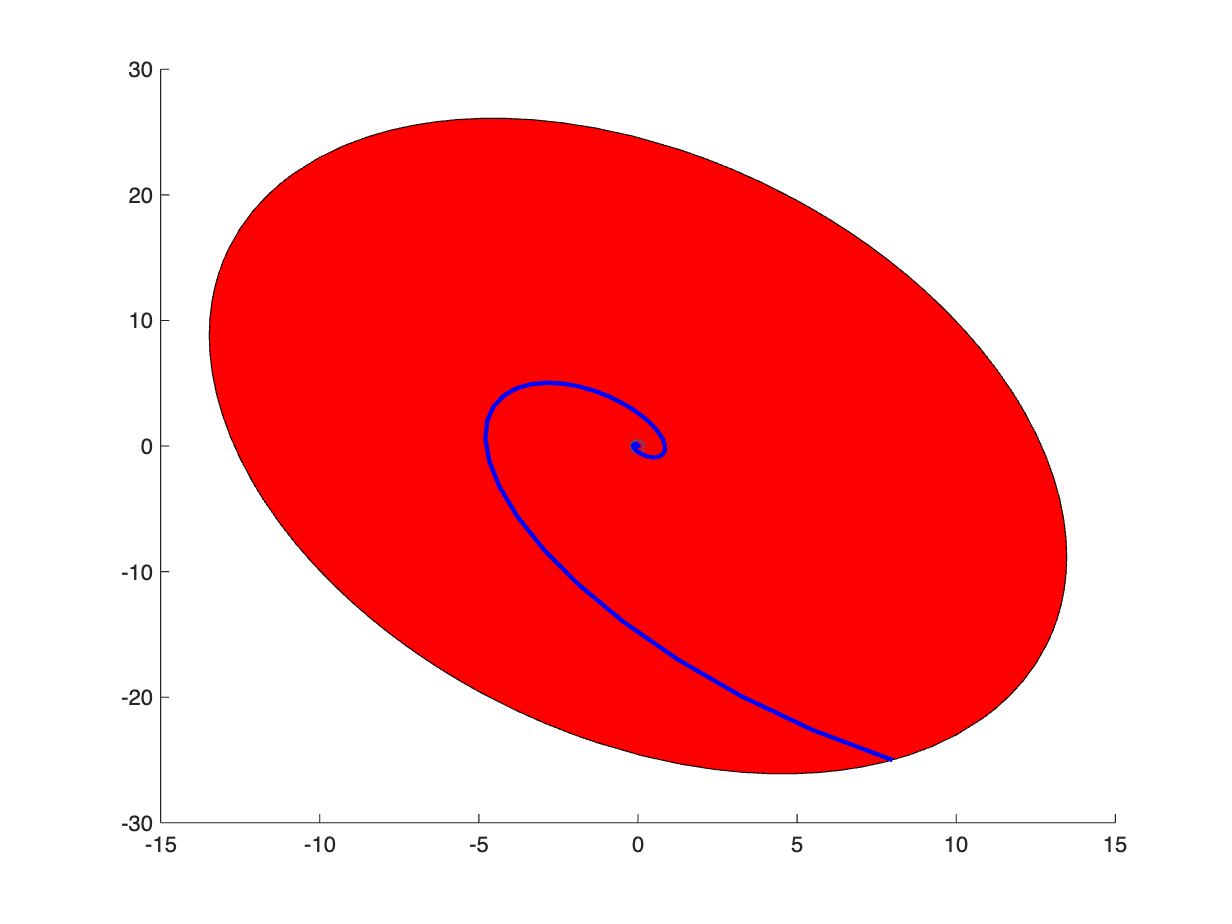

q = [0; 0]; %centro dell'ellissoide
con = [1 (v_x-q)'; (v_x-q) Q] >= 0;

figure
plot(con)
hold on;
plot(q(1), q(2), 'o')
plot(x(1,:),x(2,:), LineWidth=2, Color='b')
hold off